# Analysis of the Data from Epithelial-Mesenchymal Transition (EMT)

clearvars
addpath(genpath('../'))

## Data Loading and Pre-processing

load emt.mat
data_raw = data;
data = double(data_raw)';
data = log(data+1);
data = (data-mean(data))./std(data);
[N_cell,N_genes] = size(data);

## cluster number inference from EPI

par.choice_distance = 'cosine';
out = EstClusterNum(data,par);

Mean value of sigma: 0.31814
Minimum value of sigma: 0.17427
Maximum value of sigma: 0.54514


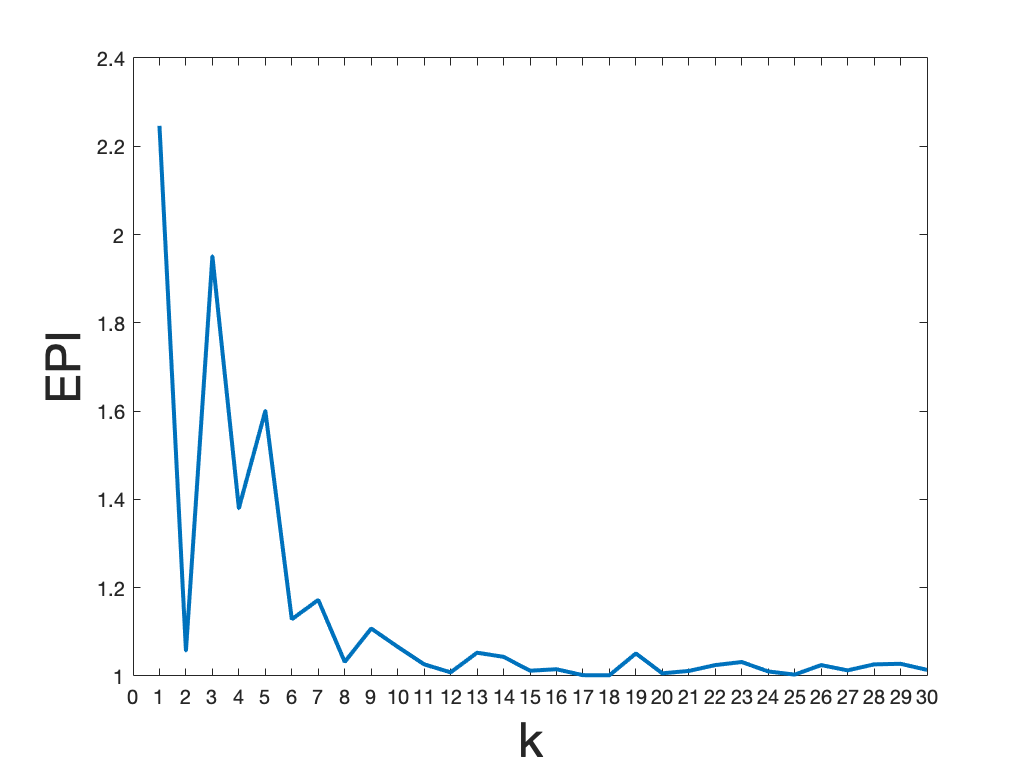

plot(out.ratio(1:30),'linewidth',2.0)
xlabel('k', 'FontSize', 24);
ylabel('EPI', 'FontSize', 24);
xticks(0:30);

## MuTrans Dynamical Analysis of the Single-Cell Data

parameter and option settings

rng(1)
par.perplex = 150;
par.K_cluster = 3;
par.trails = 100;

% Dynamical Analysis and Output
tic;
Output = DynamicalAnalysis (data, par);

Mean value of sigma: 0.32322
Minimum value of sigma: 0.17809
Maximum value of sigma: 0.55449
Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 39.9362
Iteration 20: error is 38.9726
Iteration 30: error is 38.8242
Iteration 40: error is 38.7715
Iteration 50: error is 38.8351
Iteration 60: error is 39.2251
Iteration 70: error is 39.501
Iteration 80: error is 38.9632
Iteration 90: error is 38.9589
Iteration 100: error is 2.7378
Iteration 110: error is 1.2881
Iteration 120: error is 0.89344
Iteration 130: error is 0.82907
Iteration 140: error is 0.80289
Iteration 150: error is 0.78541
Iteration 160: error is 0.77
Iteration 170: error is 0.76193
Iteration 180: error is 0.75586
Iteration 190: error is 0.74816
Iteration 200: error is 0.74491
Iteration 210: error is 0.74188
Iteration 220: error is 0.73981
Iteration 230: error is 0.73805
Iteration 240: error is 0.73641
Iteration 250: error is 0.73574
Iteration 260: error is 0.733

J_new = 3.6918

J_new = 3.6739

J_new = 3.6684

J_new = 3.6514

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.7451
Iteration 20: error is 38.9618
Iteration 30: error is 38.8461
Iteration 40: error is 39.2274
Iteration 50: error is 38.919
Iteration 60: error is 39.3066
Iteration 70: error is 39.4009
Iteration 80: error is 39.4204
Iteration 90: error is 38.5392
Iteration 100: error is 2.599
Iteration 110: error is 1.3074
Iteration 120: error is 0.94443
Iteration 130: error is 0.8191
Iteration 140: error is 0.77522
Iteration 150: error is 0.75765
Iteration 160: error is 0.74724
Iteration 170: error is 0.74101
Iteration 180: error is 0.73591
Iteration 190: error is 0.73291
Iteration 200: error is 0.72762
Iteration 210: error is 0.72483
Iteration 220: error is 0.72247
Iteration 230: error is 0.72086
Iteration 240: error is 0.71929
Iteration 250: error is 0.71763
Iteration 260: error is 0.71544
Iteration 270: error is 0.71304
Iteration 280: error is 0.71123
Iteration 290: error is 0

J_new = 3.6661

J_new = 3.6456

J_new = 3.6439

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.2148
Iteration 20: error is 38.9454
Iteration 30: error is 39.1685
Iteration 40: error is 39.2285
Iteration 50: error is 39.0008
Iteration 60: error is 38.8344
Iteration 70: error is 39.4285
Iteration 80: error is 38.9363
Iteration 90: error is 39.2074
Iteration 100: error is 2.7739
Iteration 110: error is 1.6764
Iteration 120: error is 1.0987
Iteration 130: error is 0.91524
Iteration 140: error is 0.84203
Iteration 150: error is 0.79523
Iteration 160: error is 0.78381
Iteration 170: error is 0.77531
Iteration 180: error is 0.76909
Iteration 190: error is 0.76475
Iteration 200: error is 0.76194
Iteration 210: error is 0.75922
Iteration 220: error is 0.75718
Iteration 230: error is 0.75575
Iteration 240: error is 0.75372
Iteration 250: error is 0.75309
Iteration 260: error is 0.75086
Iteration 270: error is 0.74876
Iteration 280: error is 0.74726
Iteration 290: error is

J_new = 3.6969

J_new = 3.6949

J_new = 3.6927

J_new = 3.6820

J_new = 3.6784

J_new = 3.6742

J_new = 3.6723

J_new = 3.6664

J_new = 3.6598

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 41.0325
Iteration 20: error is 39.3411
Iteration 30: error is 39.0633
Iteration 40: error is 39.6634
Iteration 50: error is 38.7398
Iteration 60: error is 38.6214
Iteration 70: error is 40.1035
Iteration 80: error is 38.7378
Iteration 90: error is 39.1593
Iteration 100: error is 2.8016
Iteration 110: error is 1.4428
Iteration 120: error is 0.97223
Iteration 130: error is 0.87372
Iteration 140: error is 0.85255
Iteration 150: error is 0.83837
Iteration 160: error is 0.82922
Iteration 170: error is 0.81635
Iteration 180: error is 0.81103
Iteration 190: error is 0.79632
Iteration 200: error is 0.78974
Iteration 210: error is 0.78471
Iteration 220: error is 0.78187
Iteration 230: error is 0.77976
Iteration 240: error is 0.77742
Iteration 250: error is 0.77578
Iteration 260: error is 0.77317
Iteration 270: error is 0.77093
Iteration 280: error is 0.7694
Iteration 290: error is

J_new = 3.6834

J_new = 3.6752

J_new = 3.6692

J_new = 3.6616

J_new = 3.6569

J_new = 3.6465

J_new = 3.6392

J_new = 3.6383

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.179
Iteration 20: error is 38.3016
Iteration 30: error is 38.4452
Iteration 40: error is 38.9801
Iteration 50: error is 38.8513
Iteration 60: error is 39.073
Iteration 70: error is 39.0182
Iteration 80: error is 39.0239
Iteration 90: error is 39.3794
Iteration 100: error is 2.8325
Iteration 110: error is 1.5965
Iteration 120: error is 1.041
Iteration 130: error is 0.89341
Iteration 140: error is 0.83285
Iteration 150: error is 0.79059
Iteration 160: error is 0.77537
Iteration 170: error is 0.76925
Iteration 180: error is 0.75867
Iteration 190: error is 0.74957
Iteration 200: error is 0.74017
Iteration 210: error is 0.73736
Iteration 220: error is 0.73493
Iteration 230: error is 0.73317
Iteration 240: error is 0.73149
Iteration 250: error is 0.73014
Iteration 260: error is 0.72816
Iteration 270: error is 0.72576
Iteration 280: error is 0.72384
Iteration 290: error is 0.

J_new = 3.7040

J_new = 3.6965

J_new = 3.6861

J_new = 3.6842

J_new = 3.6784

J_new = 3.6742

J_new = 3.6723

J_new = 3.6664

J_new = 3.6598

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.1965
Iteration 20: error is 38.4318
Iteration 30: error is 38.9146
Iteration 40: error is 39.1539
Iteration 50: error is 39.2604
Iteration 60: error is 39.1936
Iteration 70: error is 39.7727
Iteration 80: error is 39.2417
Iteration 90: error is 39.7982
Iteration 100: error is 2.7001
Iteration 110: error is 1.652
Iteration 120: error is 1.086
Iteration 130: error is 0.89127
Iteration 140: error is 0.82342
Iteration 150: error is 0.80029
Iteration 160: error is 0.78523
Iteration 170: error is 0.76208
Iteration 180: error is 0.75045
Iteration 190: error is 0.7452
Iteration 200: error is 0.74268
Iteration 210: error is 0.73829
Iteration 220: error is 0.73527
Iteration 230: error is 0.73285
Iteration 240: error is 0.72906
Iteration 250: error is 0.72468
Iteration 260: error is 0.72097
Iteration 270: error is 0.72161
Iteration 280: error is 0.71619
Iteration 290: error is 0.

J_new = 3.6863

J_new = 3.6776

J_new = 3.6594

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.08
Iteration 20: error is 38.9809
Iteration 30: error is 38.7702
Iteration 40: error is 38.8414
Iteration 50: error is 39.2922
Iteration 60: error is 38.4783
Iteration 70: error is 38.4834
Iteration 80: error is 39.4465
Iteration 90: error is 39.07
Iteration 100: error is 2.7045
Iteration 110: error is 1.4631
Iteration 120: error is 1.0411
Iteration 130: error is 0.88016
Iteration 140: error is 0.83397
Iteration 150: error is 0.79242
Iteration 160: error is 0.77745
Iteration 170: error is 0.76841
Iteration 180: error is 0.76289
Iteration 190: error is 0.75814
Iteration 200: error is 0.75522
Iteration 210: error is 0.75213
Iteration 220: error is 0.74957
Iteration 230: error is 0.74721
Iteration 240: error is 0.74557
Iteration 250: error is 0.7439
Iteration 260: error is 0.74169
Iteration 270: error is 0.73837
Iteration 280: error is 0.73549
Iteration 290: error is 0.73

J_new = 3.6899

J_new = 3.6855

J_new = 3.6748

J_new = 3.6728

J_new = 3.6685

J_new = 3.6660

J_new = 3.6578

J_new = 3.6465

J_new = 3.6392

J_new = 3.6383

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 39.7571
Iteration 20: error is 38.9729
Iteration 30: error is 38.4796
Iteration 40: error is 39.5342
Iteration 50: error is 38.7719
Iteration 60: error is 39.6383
Iteration 70: error is 39.209
Iteration 80: error is 39.8573
Iteration 90: error is 39.3033
Iteration 100: error is 2.7864
Iteration 110: error is 1.456
Iteration 120: error is 0.93694
Iteration 130: error is 0.81041
Iteration 140: error is 0.78004
Iteration 150: error is 0.76553
Iteration 160: error is 0.75681
Iteration 170: error is 0.75113
Iteration 180: error is 0.74628
Iteration 190: error is 0.74208
Iteration 200: error is 0.73786
Iteration 210: error is 0.73552
Iteration 220: error is 0.73343
Iteration 230: error is 0.73172
Iteration 240: error is 0.73002
Iteration 250: error is 0.72889
Iteration 260: error is 0.72657
Iteration 270: error is 0.72385
Iteration 280: error is 0.72189
Iteration 290: error is 

J_new = 3.7069

J_new = 3.6916

J_new = 3.6879

J_new = 3.6845

J_new = 3.6740

J_new = 3.6731

J_new = 3.6698

J_new = 3.6667

J_new = 3.6578

J_new = 3.6465

J_new = 3.6392

J_new = 3.6383

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.5487
Iteration 20: error is 38.5803
Iteration 30: error is 39.2751
Iteration 40: error is 39.3446
Iteration 50: error is 37.9407
Iteration 60: error is 38.6197
Iteration 70: error is 39.1545
Iteration 80: error is 38.7356
Iteration 90: error is 39.5674
Iteration 100: error is 2.6905
Iteration 110: error is 1.3675
Iteration 120: error is 0.98181
Iteration 130: error is 0.89205
Iteration 140: error is 0.79208
Iteration 150: error is 0.76531
Iteration 160: error is 0.75292
Iteration 170: error is 0.74463
Iteration 180: error is 0.73937
Iteration 190: error is 0.73586
Iteration 200: error is 0.7323
Iteration 210: error is 0.72925
Iteration 220: error is 0.72709
Iteration 230: error is 0.72522
Iteration 240: error is 0.72363
Iteration 250: error is 0.7223
Iteration 260: error is 0.72022
Iteration 270: error is 0.71793
Iteration 280: error is 0.71615
Iteration 290: error is 

J_new = 3.7031

J_new = 3.6895

J_new = 3.6845

J_new = 3.6740

J_new = 3.6731

J_new = 3.6698

J_new = 3.6667

J_new = 3.6578

J_new = 3.6465

J_new = 3.6392

J_new = 3.6383

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.1664
Iteration 20: error is 38.8326
Iteration 30: error is 39.2885
Iteration 40: error is 38.5749
Iteration 50: error is 38.6575
Iteration 60: error is 39.3464
Iteration 70: error is 38.8147
Iteration 80: error is 39.2263
Iteration 90: error is 39.9334
Iteration 100: error is 2.784
Iteration 110: error is 1.5344
Iteration 120: error is 1.0363
Iteration 130: error is 0.87781
Iteration 140: error is 0.82812
Iteration 150: error is 0.81958
Iteration 160: error is 0.80666
Iteration 170: error is 0.79509
Iteration 180: error is 0.7893
Iteration 190: error is 0.786
Iteration 200: error is 0.78216
Iteration 210: error is 0.77904
Iteration 220: error is 0.77691
Iteration 230: error is 0.77466
Iteration 240: error is 0.77264
Iteration 250: error is 0.76997
Iteration 260: error is 0.76487
Iteration 270: error is 0.76243
Iteration 280: error is 0.75848
Iteration 290: error is 0.7

J_new = 3.6902

J_new = 3.6824

J_new = 3.6789

J_new = 3.6735

J_new = 3.6727

J_new = 3.6698

J_new = 3.6667

J_new = 3.6578

J_new = 3.6465

J_new = 3.6392

J_new = 3.6383

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.4388
Iteration 20: error is 38.7425
Iteration 30: error is 39.8129
Iteration 40: error is 39.2901
Iteration 50: error is 39.7077
Iteration 60: error is 39.4615
Iteration 70: error is 39.3598
Iteration 80: error is 39.5325
Iteration 90: error is 39.6774
Iteration 100: error is 2.6725
Iteration 110: error is 1.3544
Iteration 120: error is 0.9465
Iteration 130: error is 0.83465
Iteration 140: error is 0.8055
Iteration 150: error is 0.79022
Iteration 160: error is 0.77941
Iteration 170: error is 0.77347
Iteration 180: error is 0.76907
Iteration 190: error is 0.76502
Iteration 200: error is 0.76172
Iteration 210: error is 0.76012
Iteration 220: error is 0.75722
Iteration 230: error is 0.75545
Iteration 240: error is 0.75381
Iteration 250: error is 0.75261
Iteration 260: error is 0.75092
Iteration 270: error is 0.74845
Iteration 280: error is 0.7467
Iteration 290: error is 0

J_new = 3.7057

J_new = 3.6985

J_new = 3.6879

J_new = 3.6845

J_new = 3.6740

J_new = 3.6731

J_new = 3.6698

J_new = 3.6667

J_new = 3.6578

J_new = 3.6465

J_new = 3.6392

J_new = 3.6383

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 41.0188
Iteration 20: error is 39.367
Iteration 30: error is 38.5172
Iteration 40: error is 39.3998
Iteration 50: error is 39.4067
Iteration 60: error is 39.1167
Iteration 70: error is 39.2142
Iteration 80: error is 39.3747
Iteration 90: error is 39.7239
Iteration 100: error is 2.8385
Iteration 110: error is 1.5412
Iteration 120: error is 0.98133
Iteration 130: error is 0.85524
Iteration 140: error is 0.80196
Iteration 150: error is 0.76903
Iteration 160: error is 0.75545
Iteration 170: error is 0.7474
Iteration 180: error is 0.74107
Iteration 190: error is 0.73542
Iteration 200: error is 0.7325
Iteration 210: error is 0.72985
Iteration 220: error is 0.727
Iteration 230: error is 0.72522
Iteration 240: error is 0.72369
Iteration 250: error is 0.7225
Iteration 260: error is 0.72028
Iteration 270: error is 0.71777
Iteration 280: error is 0.71576
Iteration 290: error is 0.71

J_new = 3.6964

J_new = 3.6743

J_new = 3.6723

J_new = 3.6664

J_new = 3.6598

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.4332
Iteration 20: error is 39.2931
Iteration 30: error is 39.2205
Iteration 40: error is 39.2892
Iteration 50: error is 39.8494
Iteration 60: error is 39.3365
Iteration 70: error is 39.949
Iteration 80: error is 40.1364
Iteration 90: error is 39.6206
Iteration 100: error is 2.806
Iteration 110: error is 1.4154
Iteration 120: error is 1.0009
Iteration 130: error is 0.82641
Iteration 140: error is 0.77456
Iteration 150: error is 0.75851
Iteration 160: error is 0.74977
Iteration 170: error is 0.7433
Iteration 180: error is 0.7384
Iteration 190: error is 0.73407
Iteration 200: error is 0.73094
Iteration 210: error is 0.72806
Iteration 220: error is 0.72621
Iteration 230: error is 0.72412
Iteration 240: error is 0.72253
Iteration 250: error is 0.72127
Iteration 260: error is 0.71924
Iteration 270: error is 0.71686
Iteration 280: error is 0.71519
Iteration 290: error is 0.7

J_new = 3.6834

J_new = 3.6746

J_new = 3.6730

J_new = 3.6664

J_new = 3.6598

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 39.6477
Iteration 20: error is 38.9695
Iteration 30: error is 38.7333
Iteration 40: error is 38.9043
Iteration 50: error is 38.9789
Iteration 60: error is 39.6912
Iteration 70: error is 38.9356
Iteration 80: error is 39.1724
Iteration 90: error is 39.2358
Iteration 100: error is 2.624
Iteration 110: error is 1.4153
Iteration 120: error is 0.99166
Iteration 130: error is 0.87884
Iteration 140: error is 0.83255
Iteration 150: error is 0.81027
Iteration 160: error is 0.78967
Iteration 170: error is 0.77723
Iteration 180: error is 0.77175
Iteration 190: error is 0.76583
Iteration 200: error is 0.76161
Iteration 210: error is 0.75825
Iteration 220: error is 0.7559
Iteration 230: error is 0.75392
Iteration 240: error is 0.75232
Iteration 250: error is 0.75096
Iteration 260: error is 0.75083
Iteration 270: error is 0.74764
Iteration 280: error is 0.74622
Iteration 290: error is 

J_new = 3.6829

J_new = 3.6495

J_new = 3.6441

J_new = 3.6437

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.4617
Iteration 20: error is 38.8442
Iteration 30: error is 39.2178
Iteration 40: error is 39.0711
Iteration 50: error is 39.6639
Iteration 60: error is 38.9999
Iteration 70: error is 38.9457
Iteration 80: error is 39.5318
Iteration 90: error is 39.2959
Iteration 100: error is 2.7759
Iteration 110: error is 1.4963
Iteration 120: error is 1.0012
Iteration 130: error is 0.87261
Iteration 140: error is 0.80984
Iteration 150: error is 0.79162
Iteration 160: error is 0.76509
Iteration 170: error is 0.75552
Iteration 180: error is 0.74535
Iteration 190: error is 0.73552
Iteration 200: error is 0.73242
Iteration 210: error is 0.73009
Iteration 220: error is 0.72792
Iteration 230: error is 0.72659
Iteration 240: error is 0.72481
Iteration 250: error is 0.72331
Iteration 260: error is 0.72119
Iteration 270: error is 0.71862
Iteration 280: error is 0.71653
Iteration 290: error is

J_new = 3.6735

J_new = 3.6629

J_new = 3.6610

J_new = 3.6493

J_new = 3.6392

J_new = 3.6388

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 39.6656
Iteration 20: error is 38.6813
Iteration 30: error is 39.0853
Iteration 40: error is 38.9435
Iteration 50: error is 38.7193
Iteration 60: error is 39.6479
Iteration 70: error is 38.8933
Iteration 80: error is 39.5419
Iteration 90: error is 39.5387
Iteration 100: error is 2.7813
Iteration 110: error is 1.379
Iteration 120: error is 0.99816
Iteration 130: error is 0.90091
Iteration 140: error is 0.828
Iteration 150: error is 0.79736
Iteration 160: error is 0.78579
Iteration 170: error is 0.77887
Iteration 180: error is 0.77297
Iteration 190: error is 0.76692
Iteration 200: error is 0.75915
Iteration 210: error is 0.75515
Iteration 220: error is 0.75174
Iteration 230: error is 0.74515
Iteration 240: error is 0.73867
Iteration 250: error is 0.73632
Iteration 260: error is 0.73415
Iteration 270: error is 0.73179
Iteration 280: error is 0.72987
Iteration 290: error is 0

J_new = 3.7002

J_new = 3.6903

J_new = 3.6880

J_new = 3.6844

J_new = 3.6793

J_new = 3.6742

J_new = 3.6723

J_new = 3.6664

J_new = 3.6598

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.5941
Iteration 20: error is 38.8952
Iteration 30: error is 38.8945
Iteration 40: error is 39.081
Iteration 50: error is 39.0779
Iteration 60: error is 39.926
Iteration 70: error is 39.2905
Iteration 80: error is 39.1042
Iteration 90: error is 39.7908
Iteration 100: error is 2.5746
Iteration 110: error is 1.7064
Iteration 120: error is 1.1452
Iteration 130: error is 0.99057
Iteration 140: error is 0.89863
Iteration 150: error is 0.87054
Iteration 160: error is 0.83586
Iteration 170: error is 0.8261
Iteration 180: error is 0.81334
Iteration 190: error is 0.80606
Iteration 200: error is 0.79452
Iteration 210: error is 0.78877
Iteration 220: error is 0.79174
Iteration 230: error is 0.77874
Iteration 240: error is 0.77188
Iteration 250: error is 0.77017
Iteration 260: error is 0.76804
Iteration 270: error is 0.76549
Iteration 280: error is 0.76165
Iteration 290: error is 0.

J_new = 3.7284

J_new = 3.6968

J_new = 3.6948

J_new = 3.6927

J_new = 3.6820

J_new = 3.6784

J_new = 3.6742

J_new = 3.6723

J_new = 3.6664

J_new = 3.6598

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 39.8273
Iteration 20: error is 38.4806
Iteration 30: error is 39.0218
Iteration 40: error is 39.5027
Iteration 50: error is 39.062
Iteration 60: error is 38.7505
Iteration 70: error is 39.963
Iteration 80: error is 39.6541
Iteration 90: error is 39.1256
Iteration 100: error is 2.8054
Iteration 110: error is 1.527
Iteration 120: error is 1.0555
Iteration 130: error is 0.96882
Iteration 140: error is 0.90844
Iteration 150: error is 0.84639
Iteration 160: error is 0.81282
Iteration 170: error is 0.76015
Iteration 180: error is 0.75315
Iteration 190: error is 0.74917
Iteration 200: error is 0.74632
Iteration 210: error is 0.74377
Iteration 220: error is 0.74142
Iteration 230: error is 0.73958
Iteration 240: error is 0.73825
Iteration 250: error is 0.73712
Iteration 260: error is 0.73525
Iteration 270: error is 0.73324
Iteration 280: error is 0.7317
Iteration 290: error is 0.7

J_new = 3.6751

J_new = 3.6678

J_new = 3.6661

J_new = 3.6544

J_new = 3.6439

J_new = 3.6431

J_new = 3.6409

J_new = 3.6386

J_new = 3.6384

J_new = 3.6384

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.0532
Iteration 20: error is 38.7881
Iteration 30: error is 38.4032
Iteration 40: error is 38.9906
Iteration 50: error is 39.4356
Iteration 60: error is 38.9883
Iteration 70: error is 39.0822
Iteration 80: error is 39.374
Iteration 90: error is 39.5842
Iteration 100: error is 2.7931
Iteration 110: error is 1.5437
Iteration 120: error is 0.95182
Iteration 130: error is 0.84007
Iteration 140: error is 0.80718
Iteration 150: error is 0.78285
Iteration 160: error is 0.77307
Iteration 170: error is 0.75964
Iteration 180: error is 0.75131
Iteration 190: error is 0.74695
Iteration 200: error is 0.7438
Iteration 210: error is 0.74115
Iteration 220: error is 0.73934
Iteration 230: error is 0.73753
Iteration 240: error is 0.73579
Iteration 250: error is 0.73461
Iteration 260: error is 0.73263
Iteration 270: error is 0.73058
Iteration 280: error is 0.72909
Iteration 290: error is 

J_new = 3.6670

J_new = 3.6487

J_new = 3.6396

J_new = 3.6388

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

Mean value of sigma: 0.18717
Minimum value of sigma: 0.11115
Maximum value of sigma: 0.27474
Iteration 10: error is 40.5323
Iteration 20: error is 38.6387
Iteration 30: error is 38.1761
Iteration 40: error is 38.5269
Iteration 50: error is 38.7793
Iteration 60: error is 39.3043
Iteration 70: error is 39.1559
Iteration 80: error is 39.4385
Iteration 90: error is 39.4235
Iteration 100: error is 2.6954
Iteration 110: error is 1.4222
Iteration 120: error is 0.98975
Iteration 130: error is 0.86307
Iteration 140: error is 0.82074
Iteration 150: error is 0.79573
Iteration 160: error is 0.77956
Iteration 170: error is 0.76958
Iteration 180: error is 0.7593
Iteration 190: error is 0.74818
Iteration 200: error is 0.74221
Iteration 210: error is 0.73825
Iteration 220: error is 0.73574
Iteration 230: error is 0.73303
Iteration 240: error is 0.72803
Iteration 250: error is 0.72513
Iteration 260: error is 0.72135
Iteration 270: error is 0.71796
Iteration 280: error is 0.71558
Iteration 290: error is

J_new = 3.7057

J_new = 3.6985

J_new = 3.6879

J_new = 3.6845

J_new = 3.6740

J_new = 3.6731

J_new = 3.6698

J_new = 3.6667

J_new = 3.6578

J_new = 3.6465

J_new = 3.6392

J_new = 3.6383

J_new = 3.6363

J_new = 3.6341

J_new = 3.6339

J_new = 3.6339

E_best = 0.7571

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          3.63523                       0.00013
     1           8          3.58394        32054.8        0.00186  
     2          10          3.57643        0.44598         0.0013  
     3          12          3.56578       0.280039       0.000851  
     4          13          3.56093              1       0.000829  
     5          14            3.557              1       0.000726  
     6          16          3.55523       0.328736         0.0006  
     7          17          3.55417              1       0.000641  
     8          18          3.55233              1       0.000573  
     9          19          3.55128              1         0.0006  
    10          20          3.55024              1       0.000317  
    11          21          3.54936              1       0.000454  
    12          22          3.54868              

toc;

Elapsed time is 1.966771 seconds.


## Visualization of Results

rng(1)
class_order = Output.class_order;
H = Output.H;
data_perm = Output.data_perm;

k = par.K_cluster;
colors_class = brewermap(k,'set1');
choice_distance = 'cosine';
Dist = squareform(pdist (data_perm,choice_distance));
ydata = tsne_d(Dist,[],[],40);

Mean value of sigma: 0.20095
Minimum value of sigma: 0.1177
Maximum value of sigma: 0.28366
Iteration 10: error is 39.3603
Iteration 20: error is 38.4097
Iteration 30: error is 38.4984
Iteration 40: error is 38.8211
Iteration 50: error is 38.7838
Iteration 60: error is 39.2535
Iteration 70: error is 38.7153
Iteration 80: error is 39.4146
Iteration 90: error is 39.2564
Iteration 100: error is 2.3223
Iteration 110: error is 1.3942
Iteration 120: error is 0.90064
Iteration 130: error is 0.77604
Iteration 140: error is 0.74845
Iteration 150: error is 0.73867
Iteration 160: error is 0.73347
Iteration 170: error is 0.72971
Iteration 180: error is 0.72636
Iteration 190: error is 0.72435
Iteration 200: error is 0.72285
Iteration 210: error is 0.7217
Iteration 220: error is 0.72061
Iteration 230: error is 0.71962
Iteration 240: error is 0.71866
Iteration 250: error is 0.71775
Iteration 260: error is 0.71395
Iteration 270: error is 0.71075
Iteration 280: error is 0.70473
Iteration 290: error is 

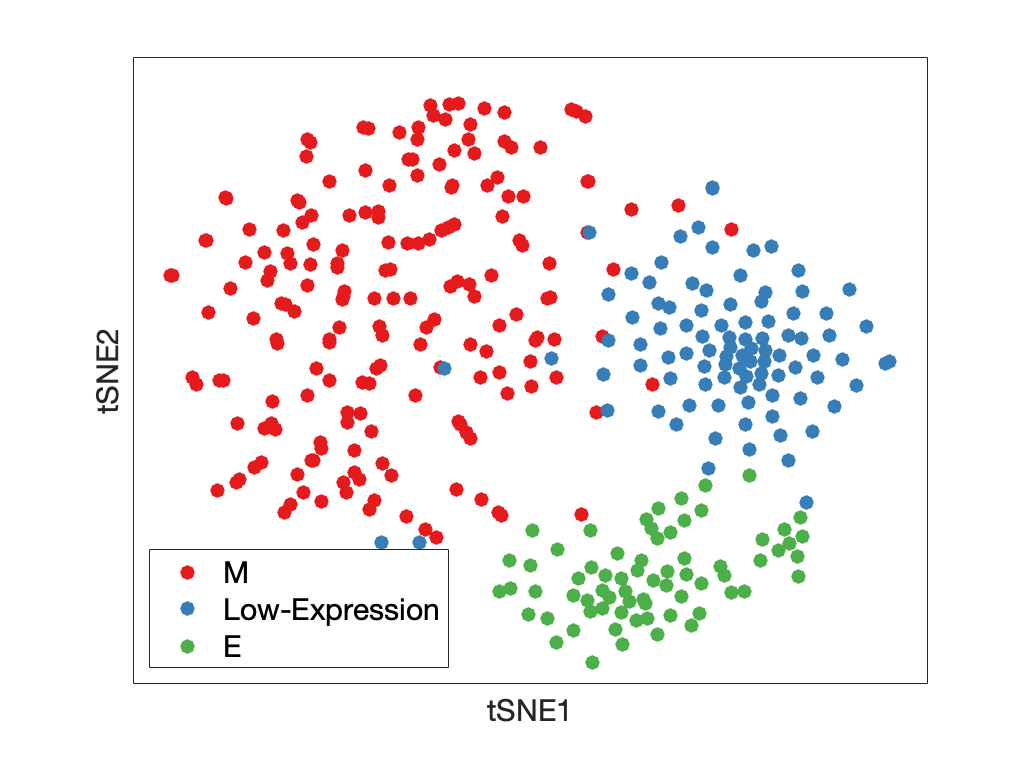

score = ydata;

% MuTrans attrractors
figure;
gscatter(score(:,1),score(:,2),class_order,colors_class,[],25);
set(gca,'xtick',[])
set(gca,'ytick',[])
legend({'M','Low-Expression','E'},'Fontsize',15,'Location','SouthWest')
xlabel('tSNE1','Fontsize',15)
ylabel('tSNE2','Fontsize',15)

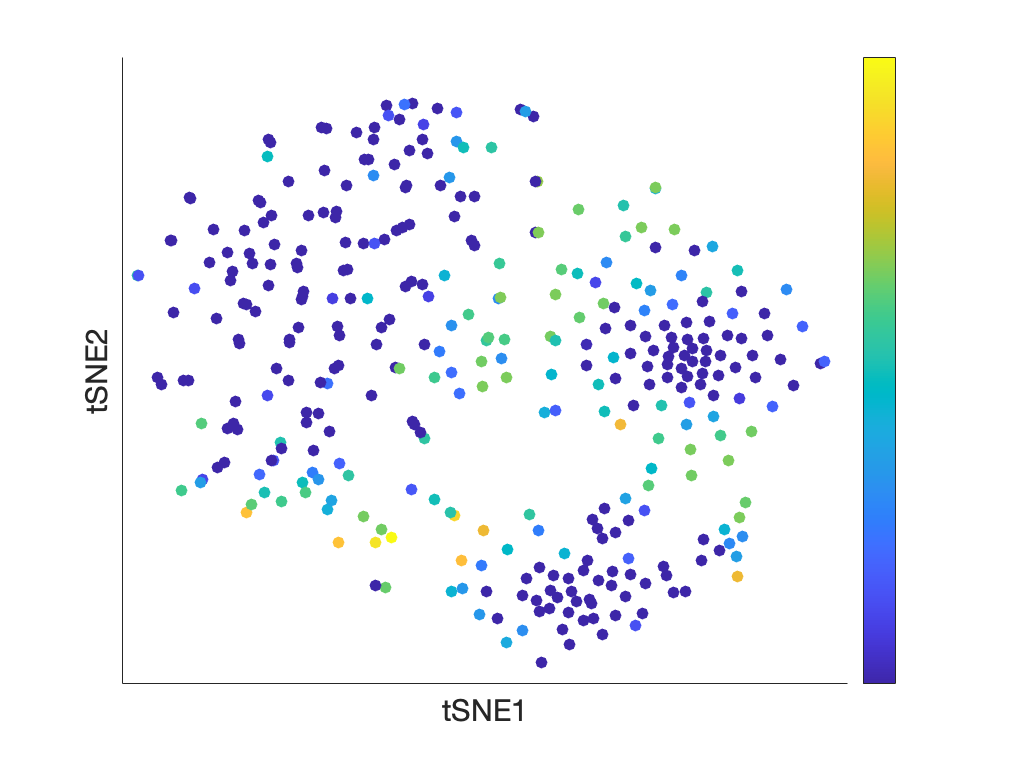


% Entropy of transition cells
figure;
scatter(score(:,1),score(:,2),[],H,'filled');
set(gca,'xtick',[])
set(gca,'ytick',[])
colorbar('Ticks',[]);
xlabel('tSNE1','Fontsize',15)
ylabel('tSNE2','Fontsize',15)

## **Infer the Cell Lineage (MPFT)**

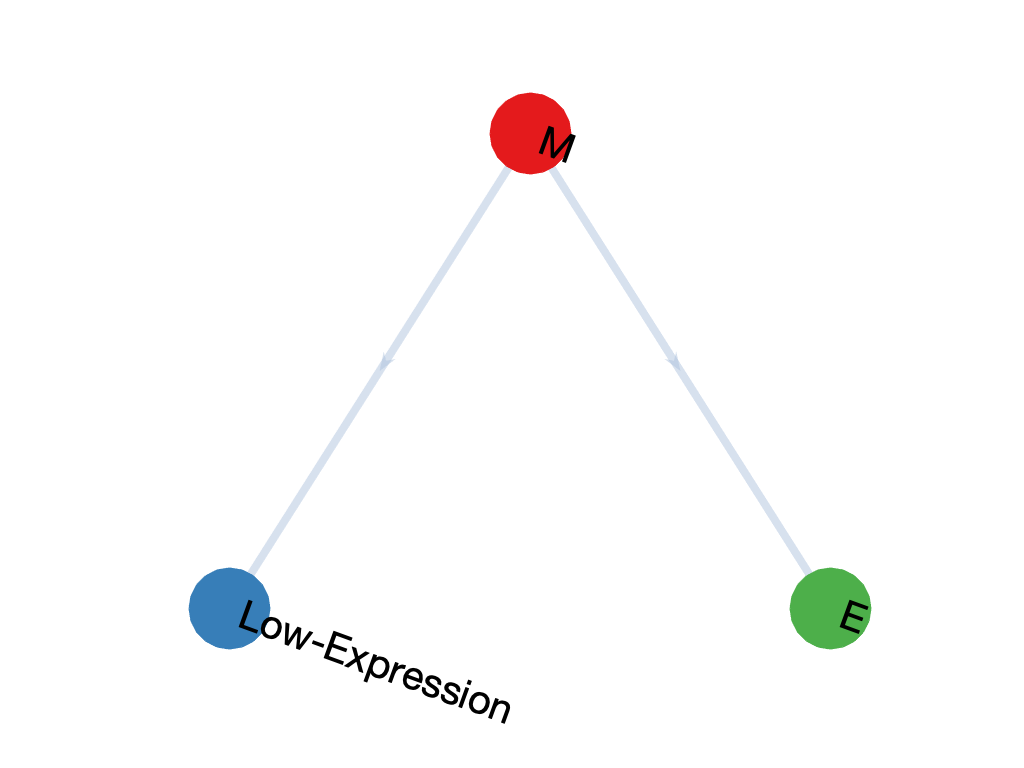

par.legend_text = {'M','Low-Expression','E'}; %can also specify root by specifying par.root
InferLineage(Output, par)

To infer the MPPT (transition trajectory), we recommend to use the python package in the new version of MuTrans.

## Cell-fate Landscape Visualization

2d Projection

P_perm = Output.P_perm;
P_rho = Output.P_rho;

w = 0.5;
P_w = w*P_perm+(1-w)*P_rho;
par.dims = 5;
par.isomap_kn = 50;
score_2d = SC_forced2d (P_w,par);

Constructing neighborhood graph...
Computing shortest paths...
Constructing low-dimensional embedding...


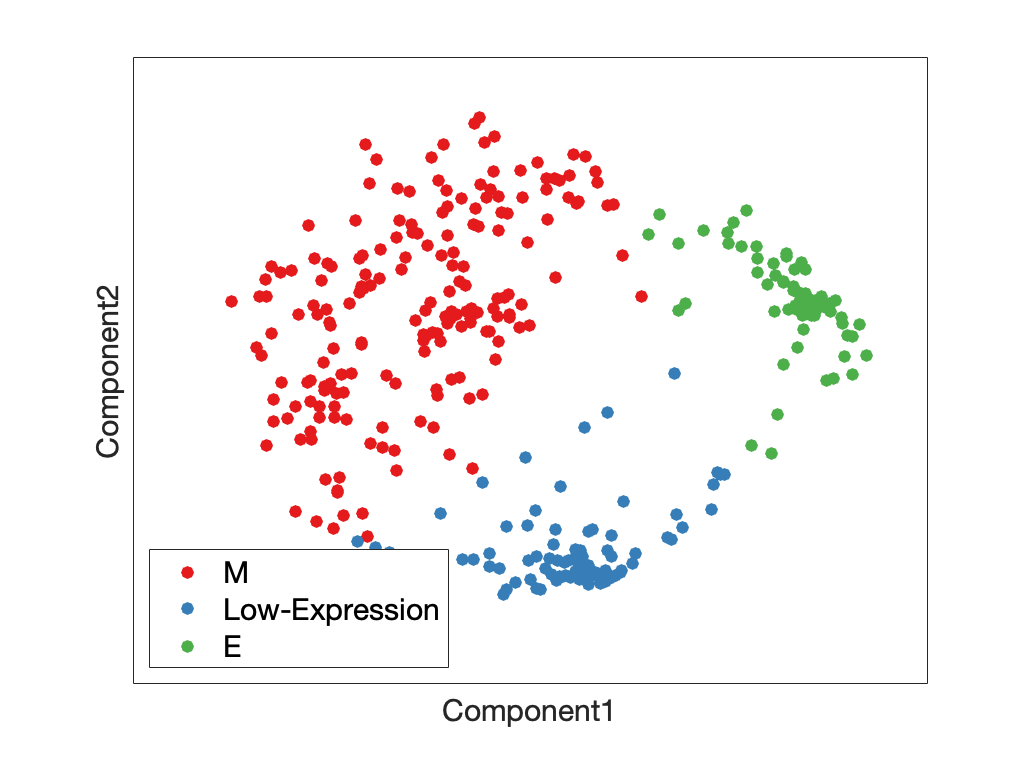


figure;
class_order = Output.class_order;
gscatter(score_2d(:,1),score_2d(:,2),class_order,colors_class,[],22);
legend({'M','Low-Expression','E'},'Fontsize',15,'Location','SouthWest')
set(gca,'xtick',[],'ytick',[]);
xlabel('Component1','Fontsize',15)
ylabel('Component2','Fontsize',15)



Output.embedding_2d = score_2d;

Landscape Construction

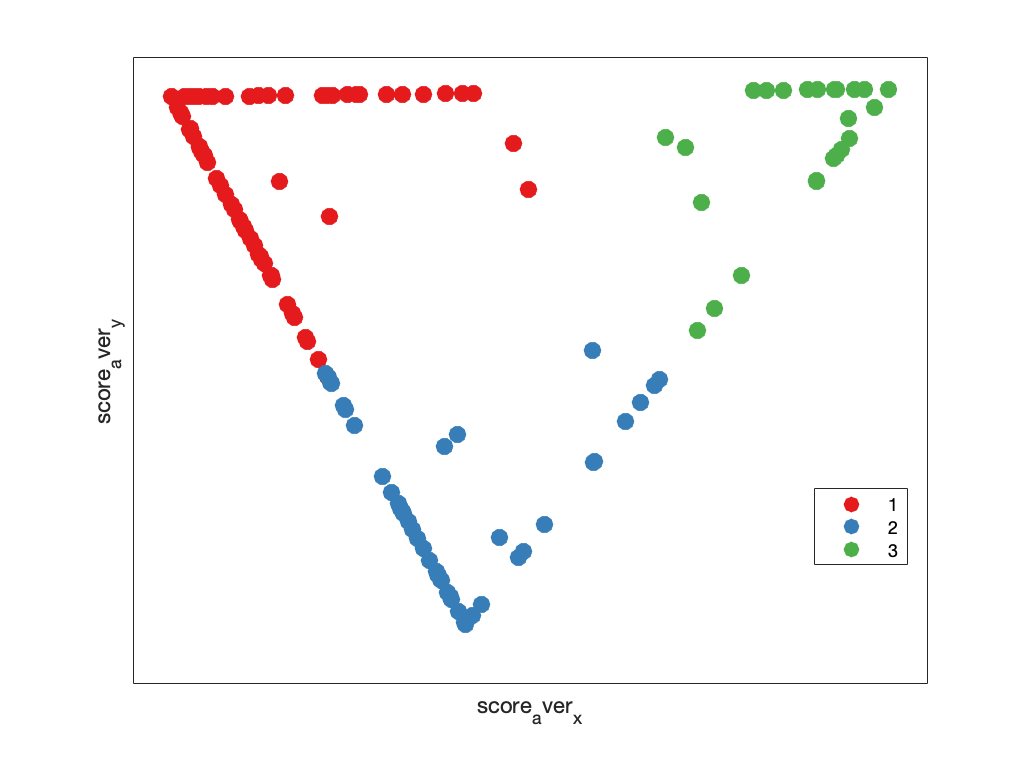

par.legend_text = {'M','Low-Expression','E'};
par.colors = colors_class ;
par.mksize = 30;
land = ConstructLandscape (Output, par);

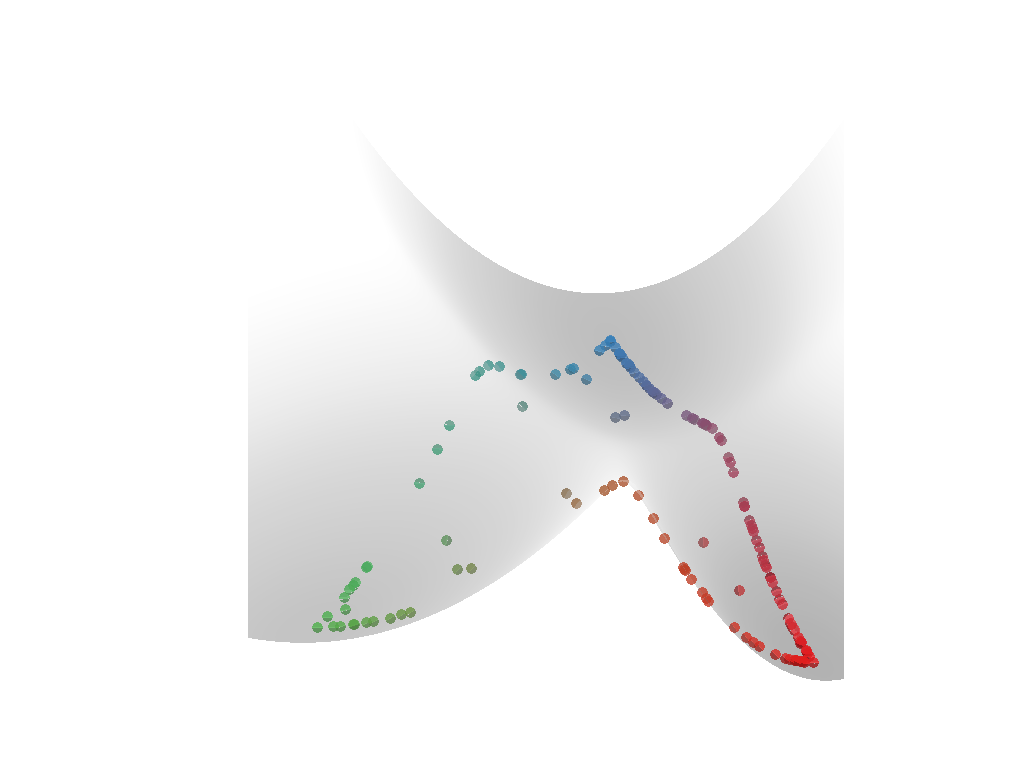

view([180 60])

## Transition Gene Analysis

labs_perm = Output.labs_perm;
par.display_genes_label = true;
par.display_mixing_id = false;
par.genes = genes;
par.thresh_de_pvalues = 1e-3;
par.thresh_ms_pvalues = 1e-4;
par.flip = false;

Direct transition from E to M

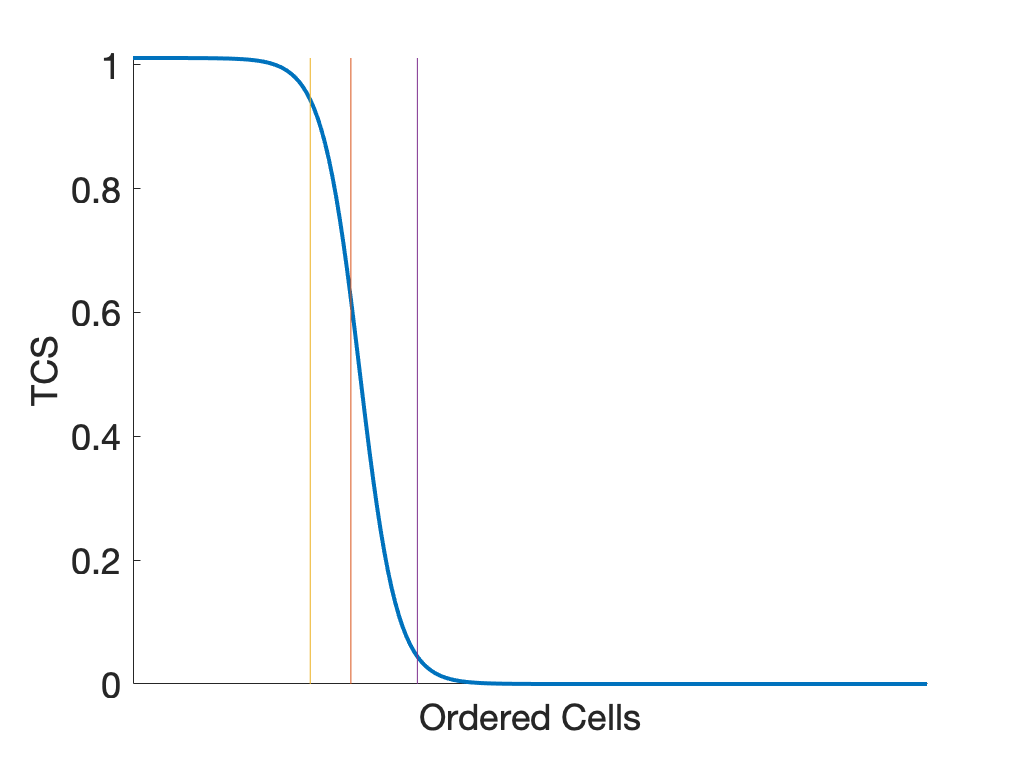

Below is the heatmap of down-regulated MS/IH genes


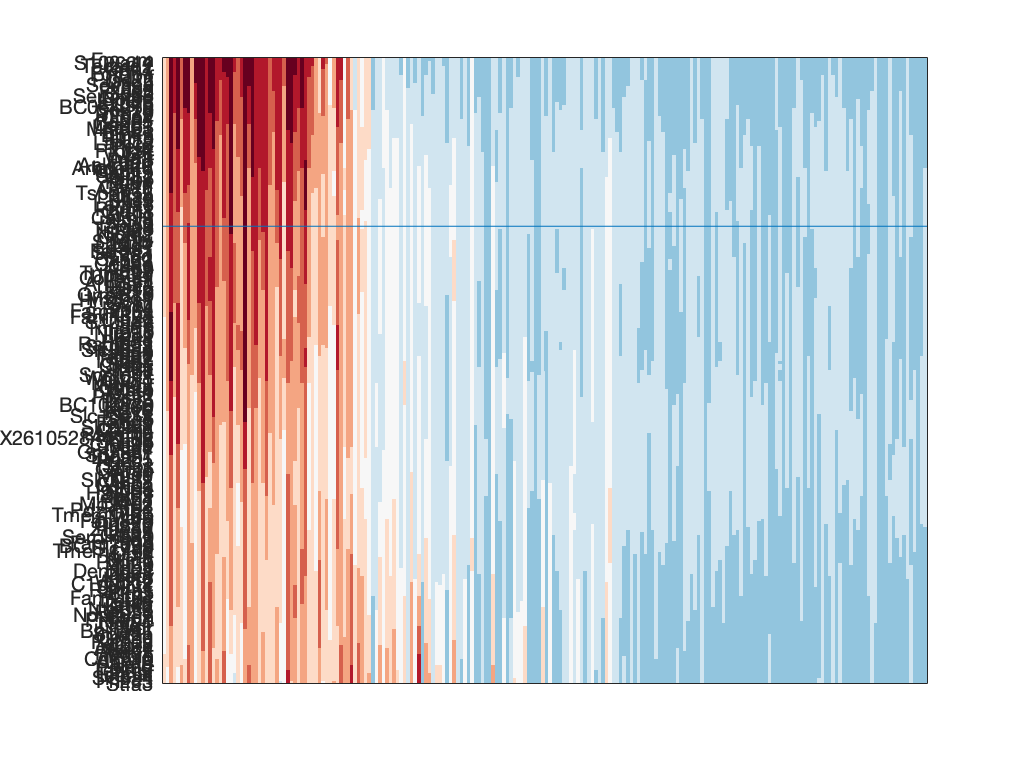

Below is the heatmap of up-regulated MS/IH genes


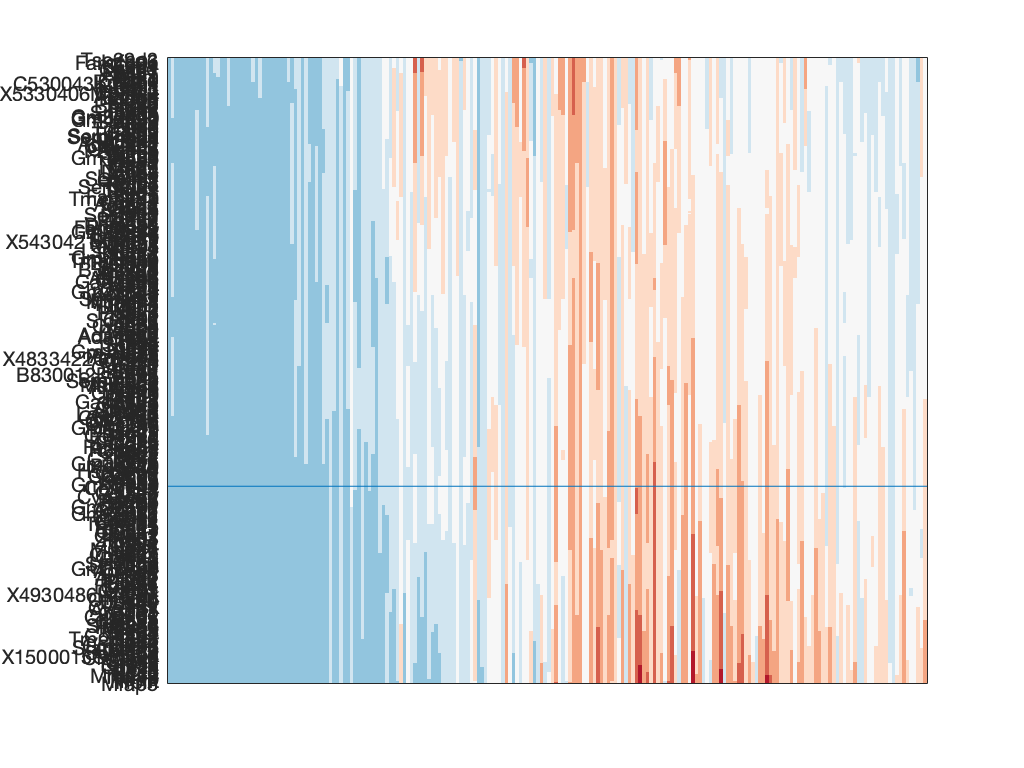

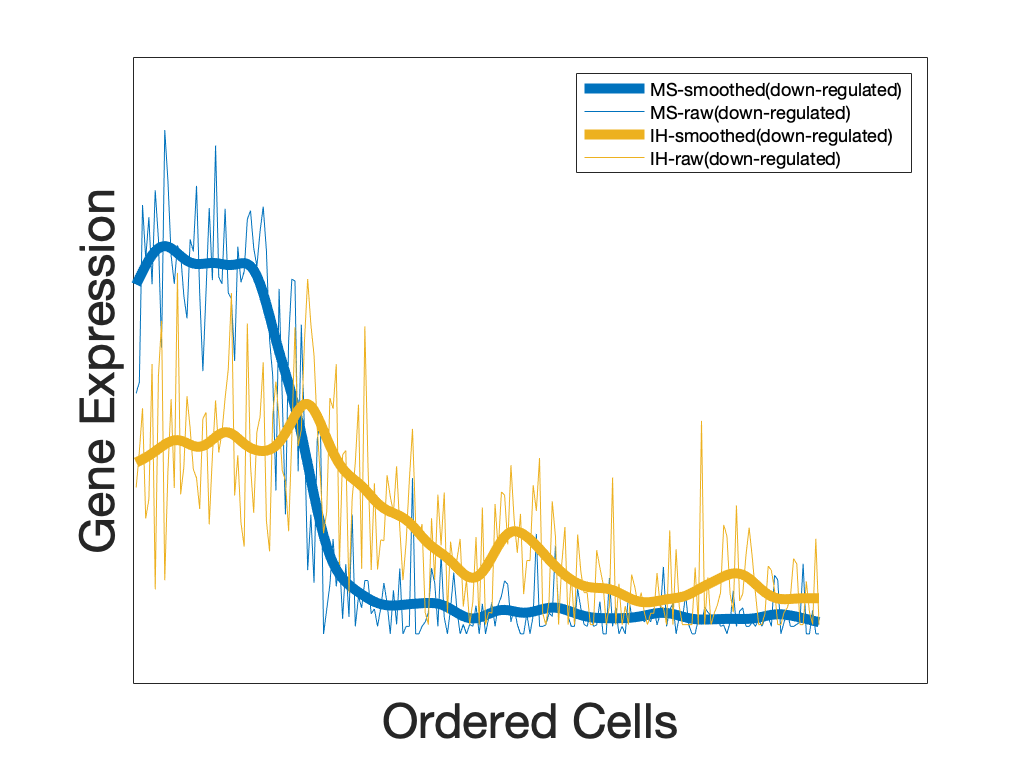

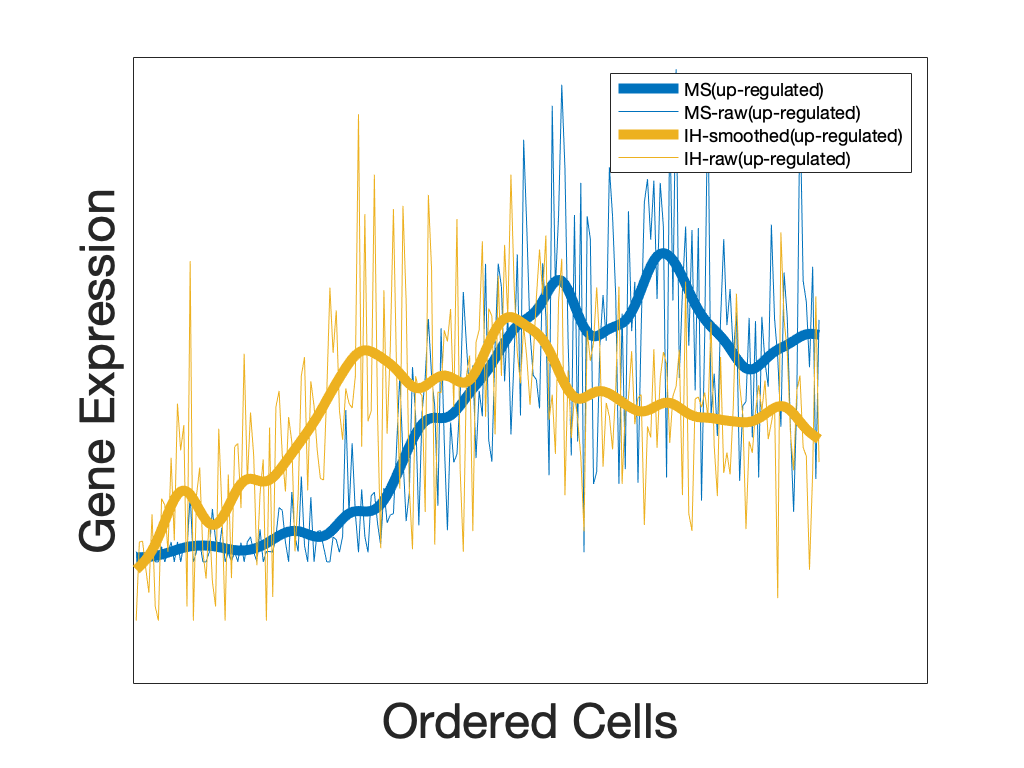

genes_analysis_out_direct = GeneAnalysis(3, 1, Output,par);

Find the list of MS genes in E state

disp(genes_analysis_out_direct.genes_ms_g1)

    {'Epcam'   }
    {'S100a14' }
    {'Tacstd2' }
    {'Cdh1'    }
    {'Krt17'   }
    {'Fgfbp1'  }
    {'Tnf'     }
    {'Prss22'  }
    {'Dsg3'    }
    {'Serinc2' }
    {'Ctsh'    }
    {'Fxyd3'   }
    {'Gpx2'    }
    {'Serpinb5'}
    {'Bcam'    }
    {'Lypd3'   }
    {'Cstb'    }
    {'BC064078'}
    {'Sox15'   }
    {'Trim29'  }
    {'Eya2'    }
    {'Cldn4'   }
    {'Rab25'   }
    {'Cdcp1'   }
    {'Lamb3'   }
    {'Mfsd2a'  }
    {'Efna1'   }
    {'Dmkn'    }
    {'Il17re'  }
    {'Il1a'    }
    {'Lamc2'   }
    {'Perp'    }
    {'Tns4'    }
    {'Ptprz1'  }
    {'Ehf'     }
    {'Vwa1'    }
    {'Fgfr3'   }
    {'Ptprf'   }
    {'Ankrd22' }
    {'Arhgef16'}
    {'Ckmt1'   }
    {'Rab15'   }
    {'Spint2'  }
    {'Itgb6'   }
    {'Krt6a'   }
    {'Il1rn'   }
    {'Car12'   }
    {'Apoc1'   }
    {'Tspan12' }
    {'Urah'    }
    {'Il24'    }
    {'Krt5'    }
    {'Lama3'   }
    {'Pitx1'   }
    {'Parm1'   }
    {'Cldn8'   }
    {'Krt14'   }
    {'Calml3'  }
    {'Sfn'    

 transition from E to LE

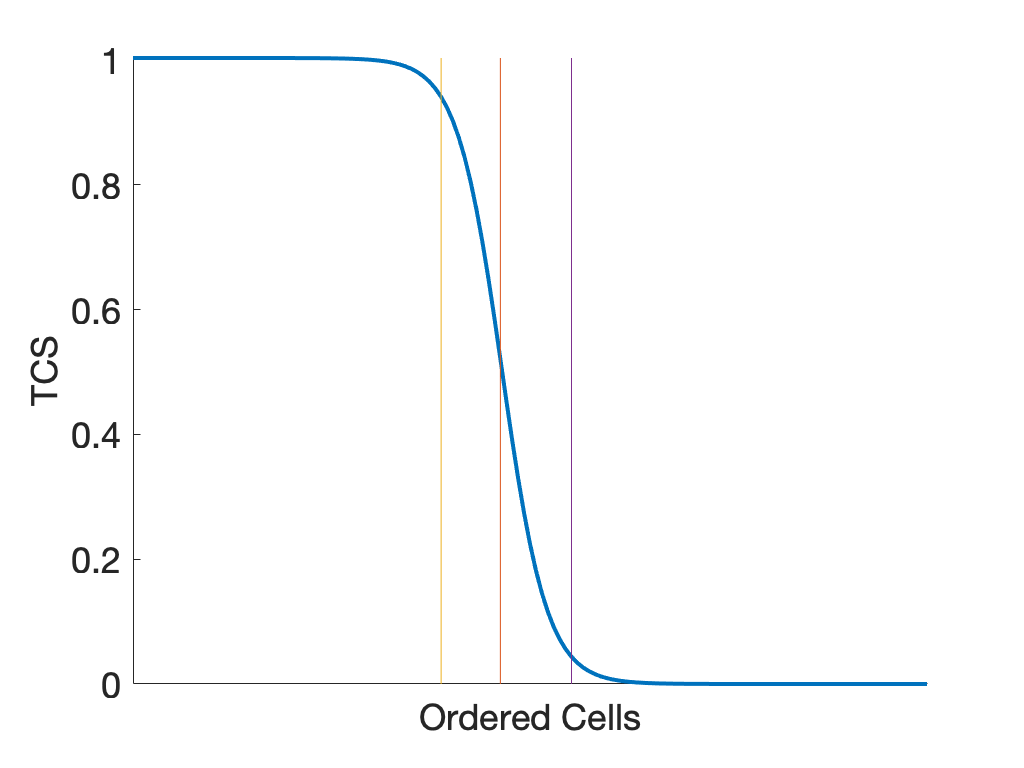

Below is the heatmap of transition genes


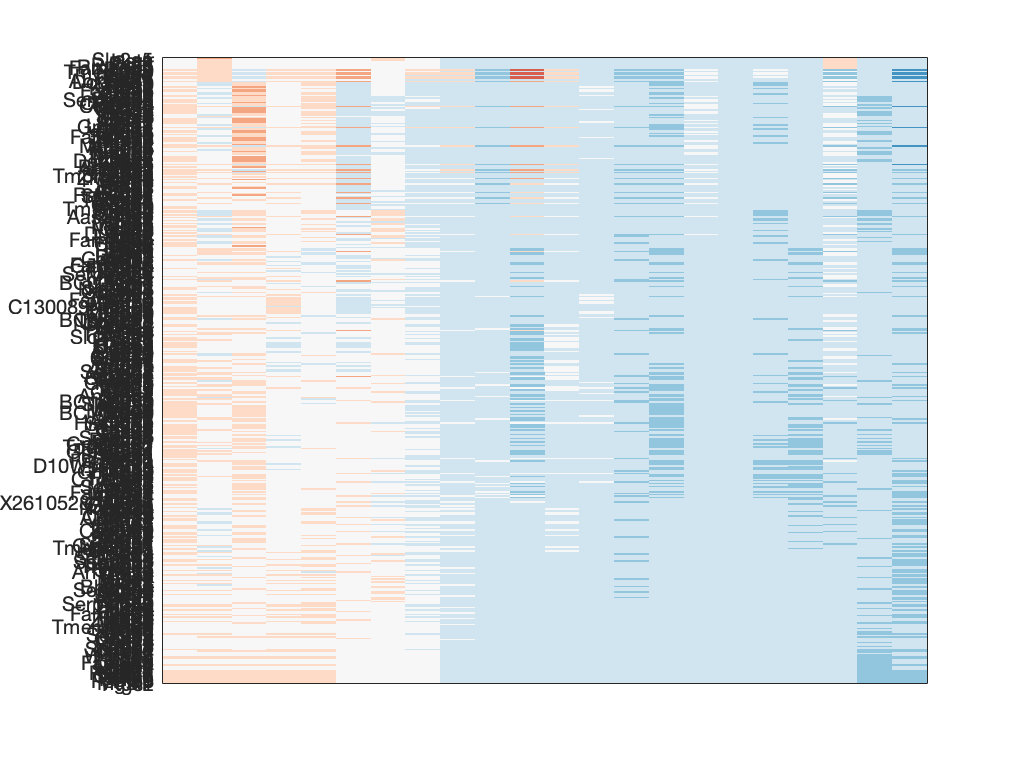

Below is the heatmap of down-regulated MS/IH genes


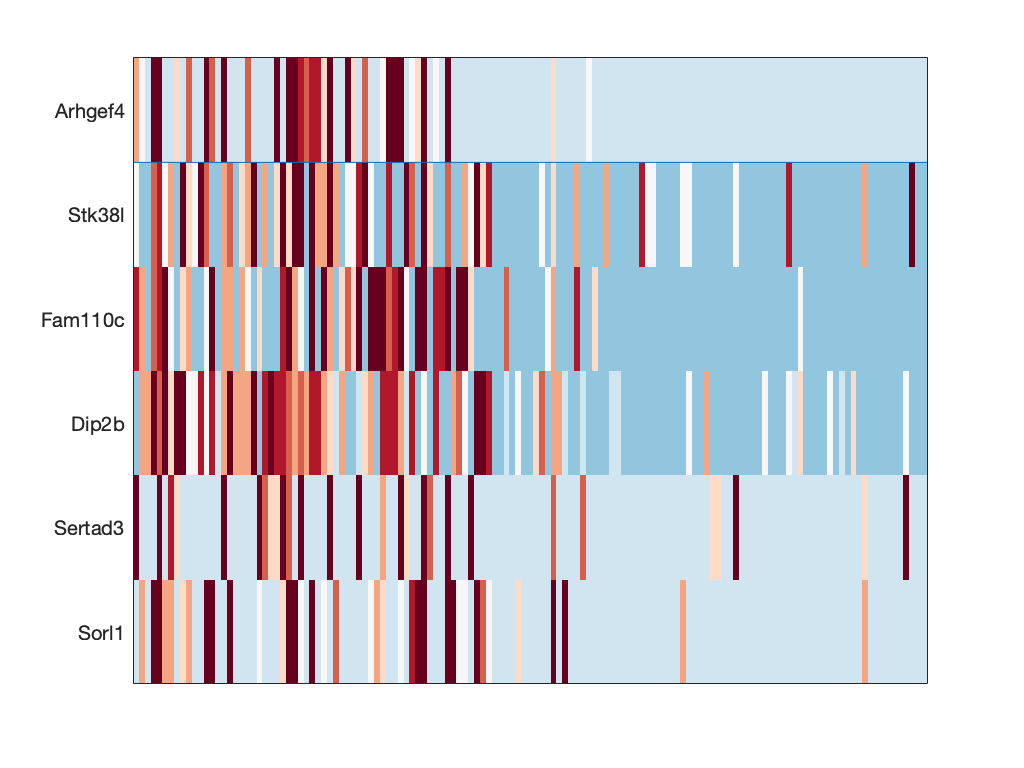

Below is the heatmap of up-regulated MS/IH genes


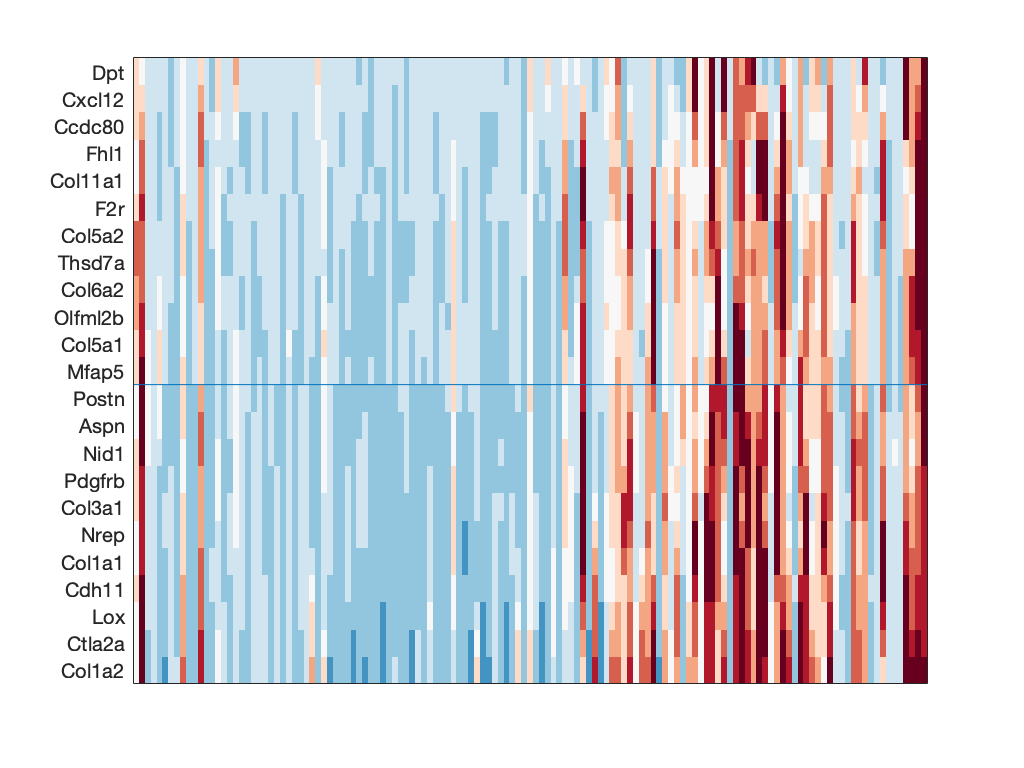

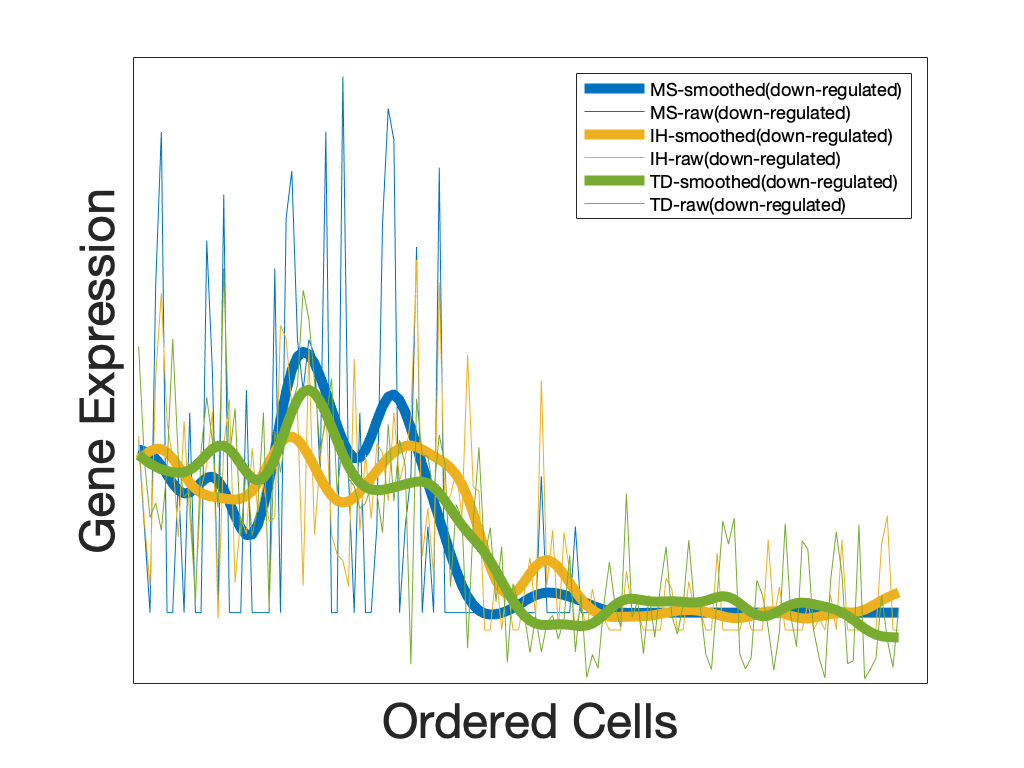

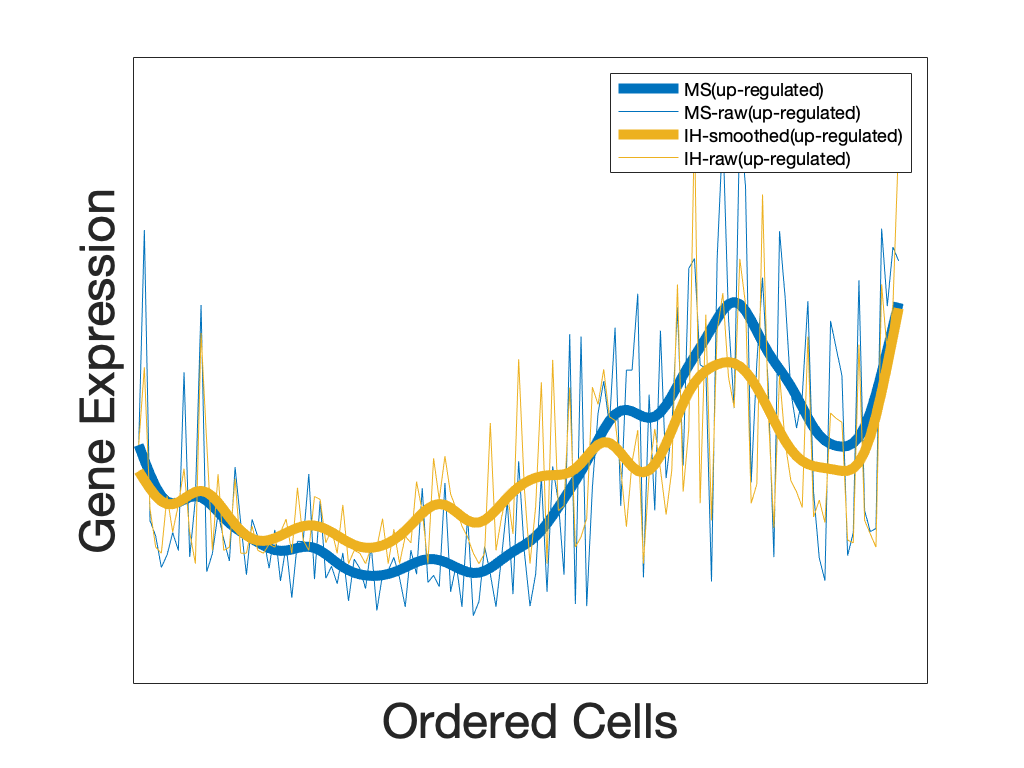

genes_analysis_out_indirect_1 = GeneAnalysis(3, 2, Output,par);

 transition from LE to M

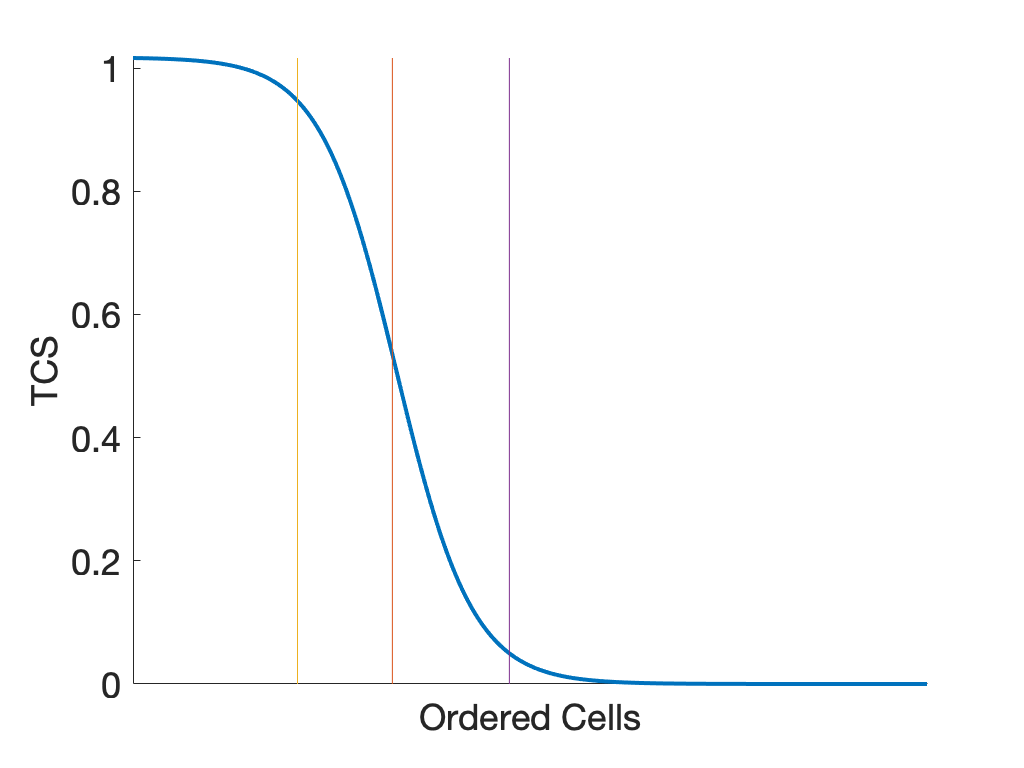

Below is the heatmap of transition genes


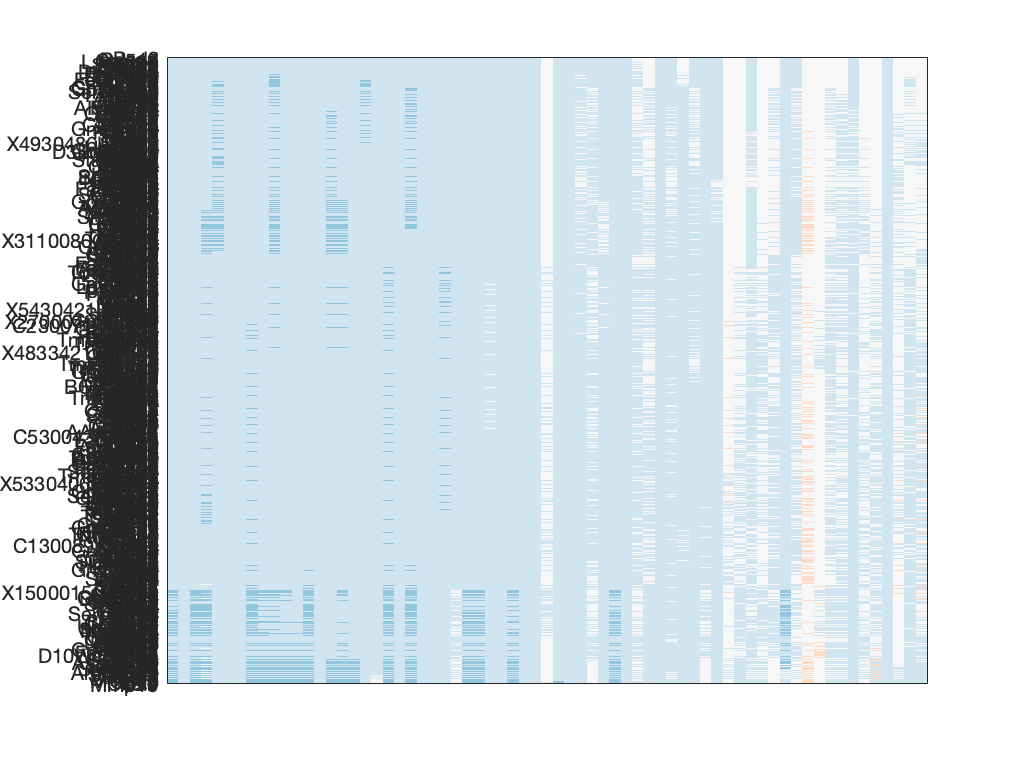

Below is the heatmap of up-regulated MS/IH genes


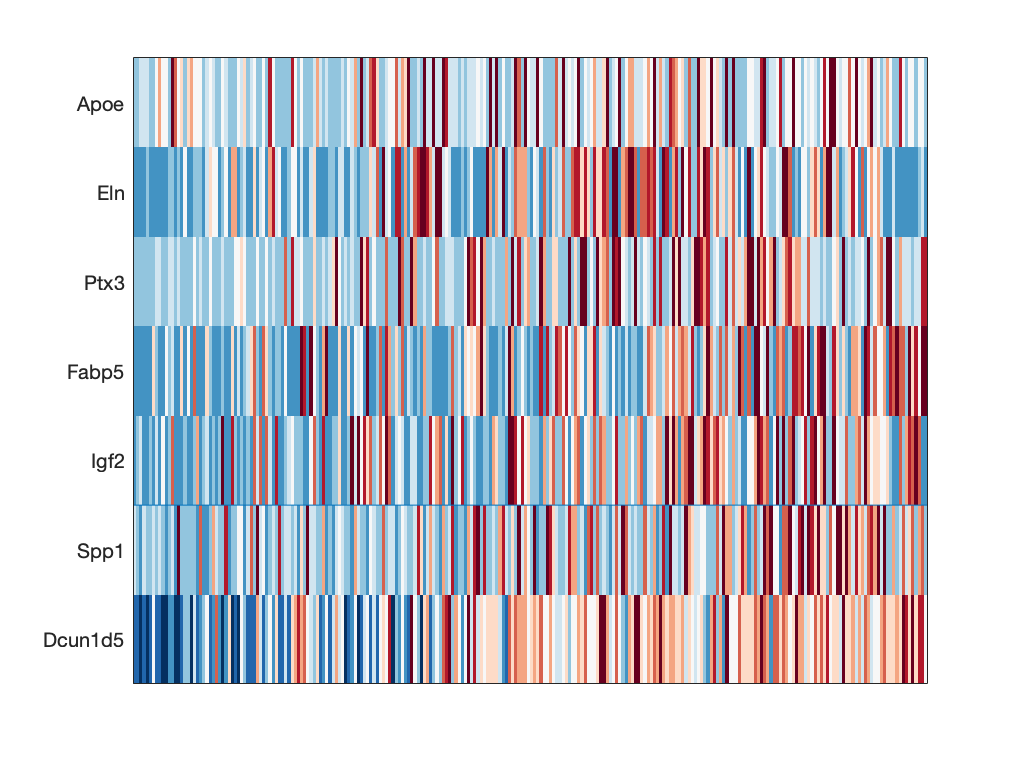

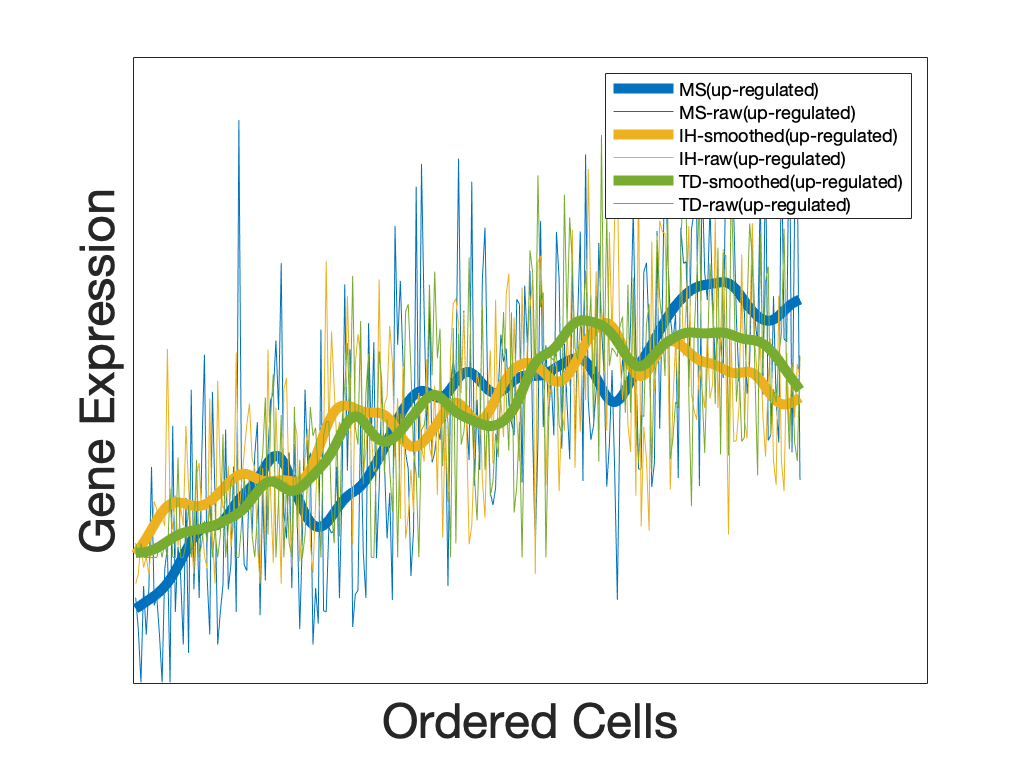

genes_analysis_out_indirect_2 = GeneAnalysis(2, 1, Output,par);

## Additonal figures of MuTrans Output

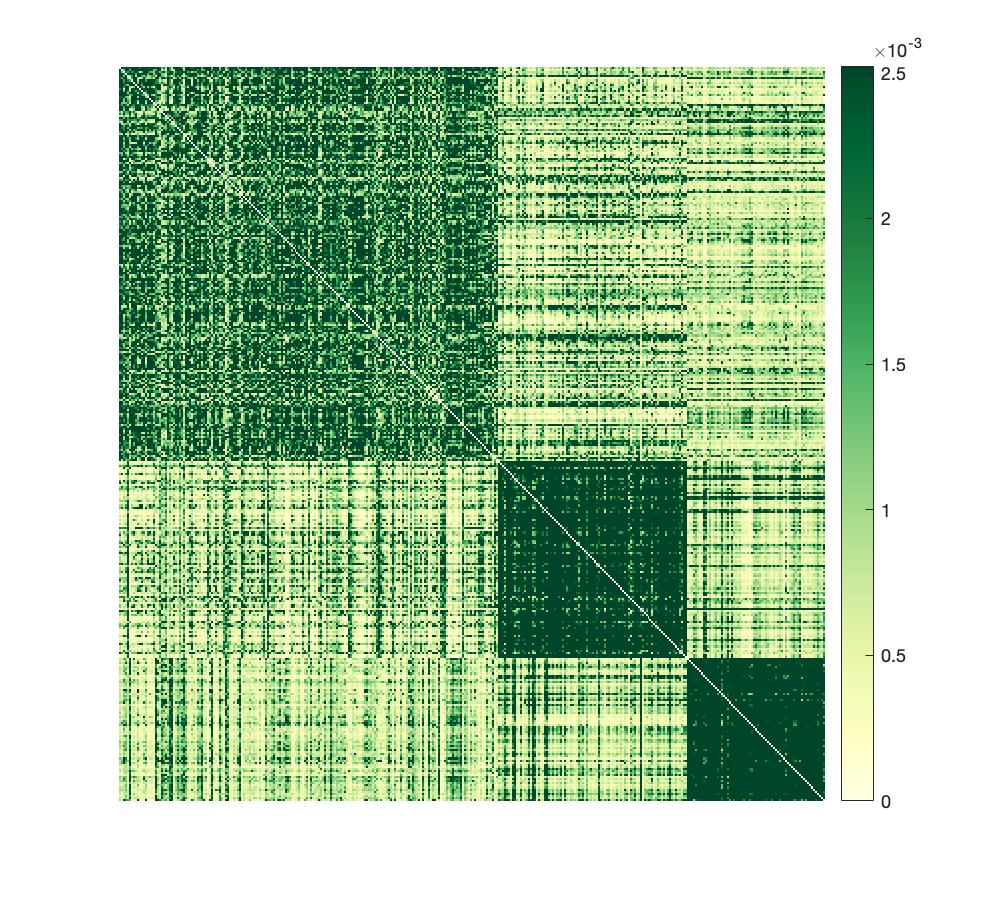

rho_class = Output.rho_class;
perm_class = Output.perm_class;
P_hat = Output.P_hat;
P_appr_perm = Output.P_appr_perm;
mu_hat = Output.mu_hat;
k = Output.k;
H = Output.H;



max_P = 0.2* max(max(P_rho));
c_lim = [0 max_P];
cmp = 'ylgn';

figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
colorbar;

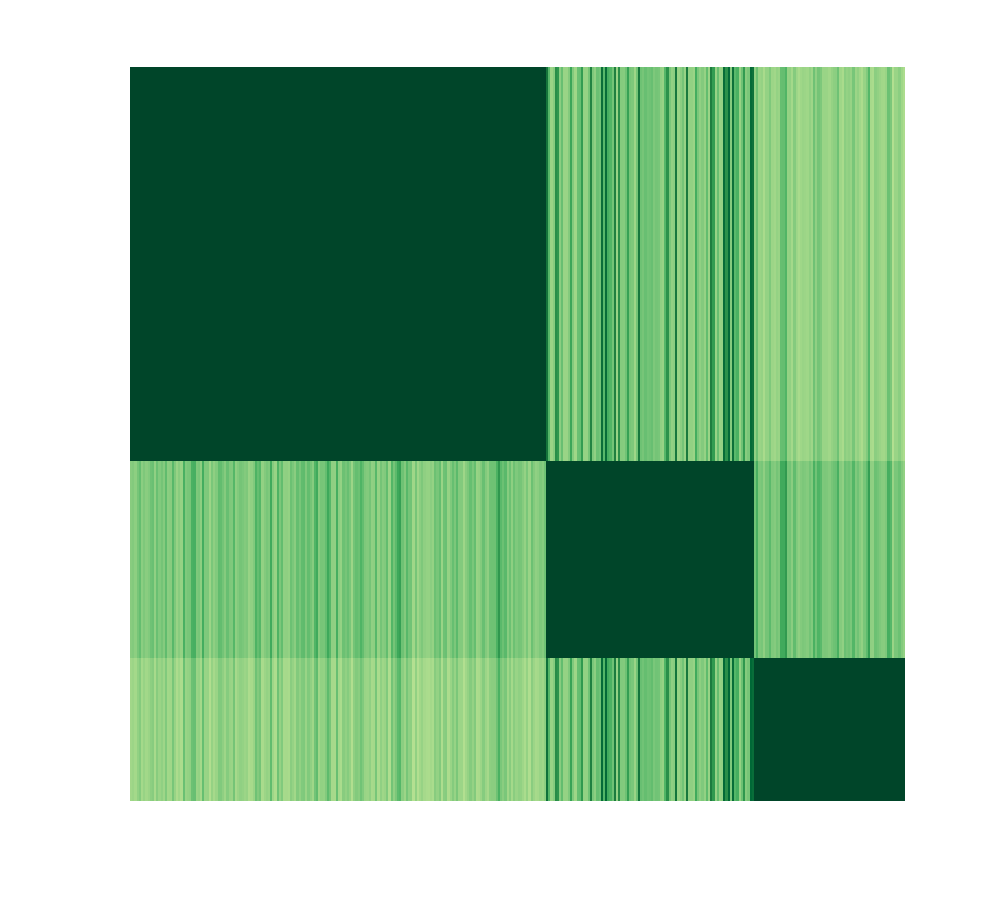



figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_appr_perm);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)

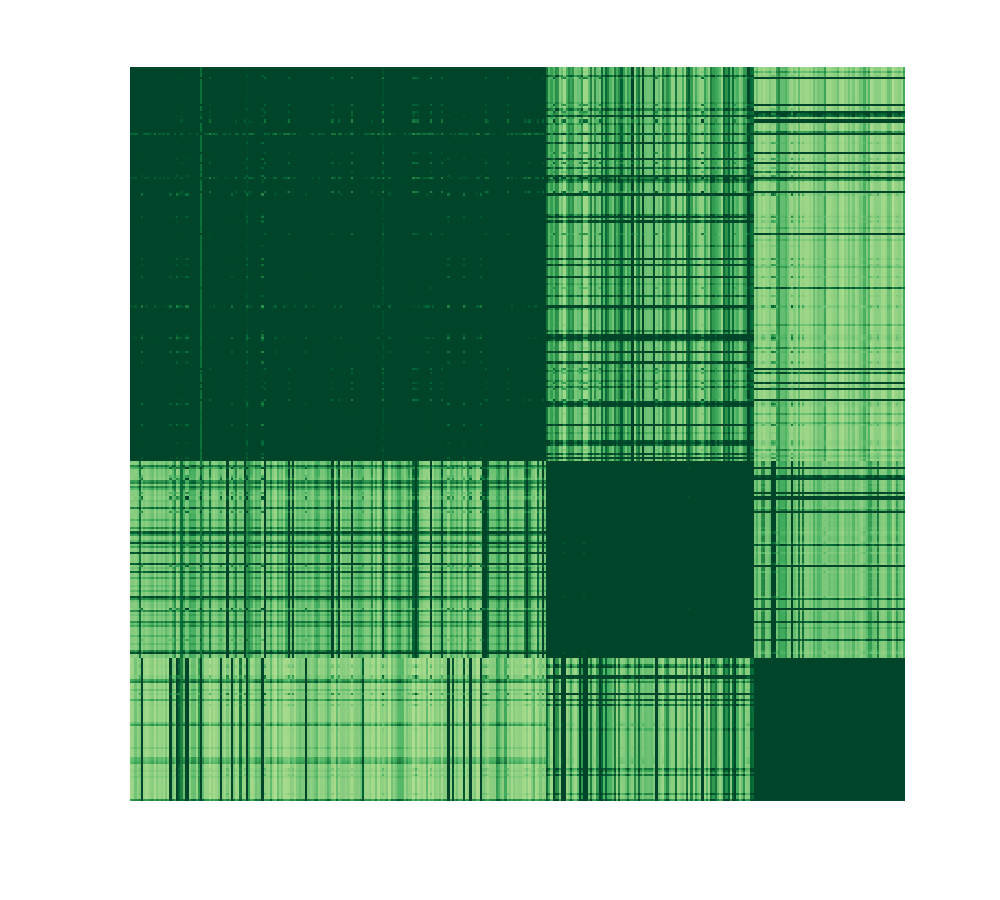

%colorbar;


figure('rend','painters','pos',[10 10 500  450])
colormap(brewermap([],cmp))
imagesc(P_rho);
axis off
set(gca,'xtick',[],'ytick',[]);
caxis(c_lim)
%colorbar;
box off

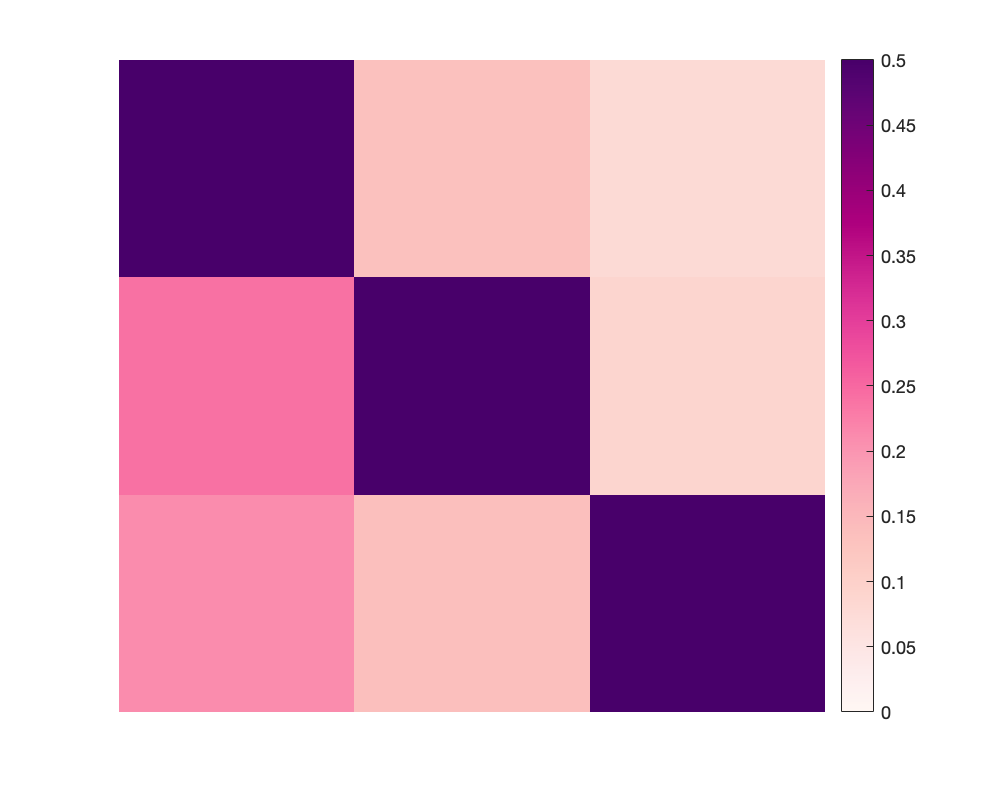



cmp = 'rdpu';
figure('rend','painters','pos',[10 10 500  400])
colormap(brewermap([],cmp))
imagesc(P_hat);
caxis([0 0.5])
axis off
set(gca,'xtick',[],'ytick',[]);
box off
colorbar;

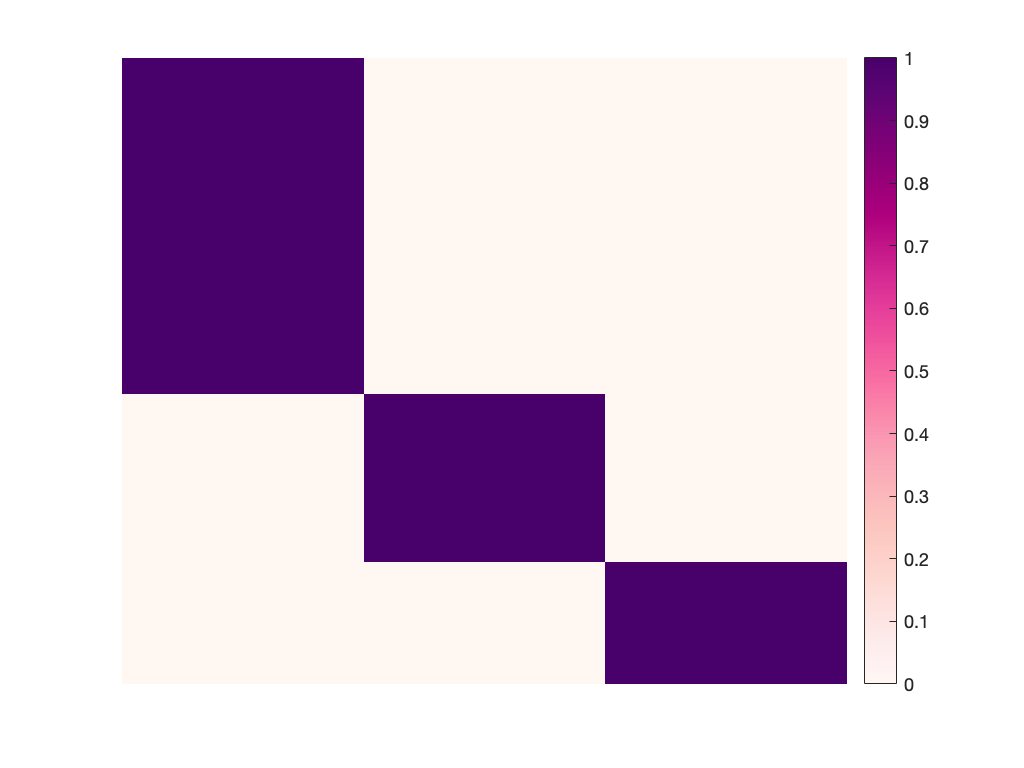


figure;
for id_cluster  = 1:k
member(:,id_cluster) = (class_order == id_cluster)';
end
colormap(brewermap([],cmp))
imagesc(member);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off

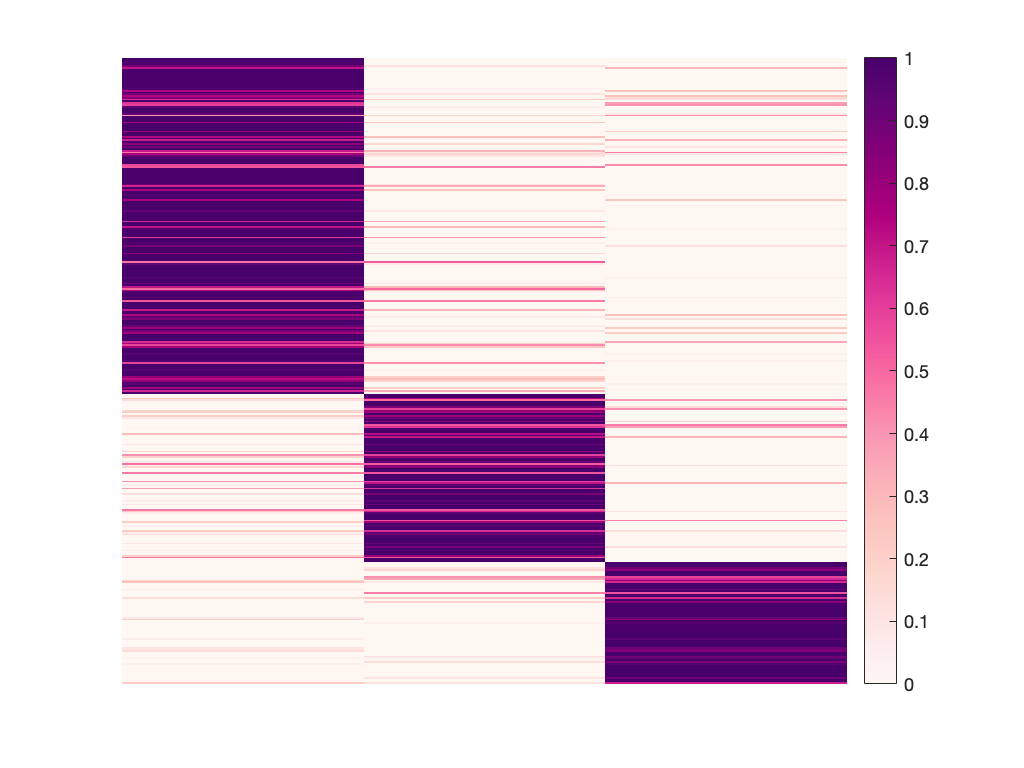


figure;
colormap(brewermap([],cmp))
imagesc(rho_class);
caxis([0 1])
colorbar;
axis off
set(gca,'xtick',[],'ytick',[]);
box off